clc
clear variables
close all

T2 = 1; %seg
num2 = 1;
den2 = [1 1 0];
sys2 = tf(num2,den2)

sys2 =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties



Gs2=c2d(sys2,T2,'zoh')

Gs2 =
 
    0.3679 z + 0.2642
  ----------------------
  z^2 - 1.368 z + 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


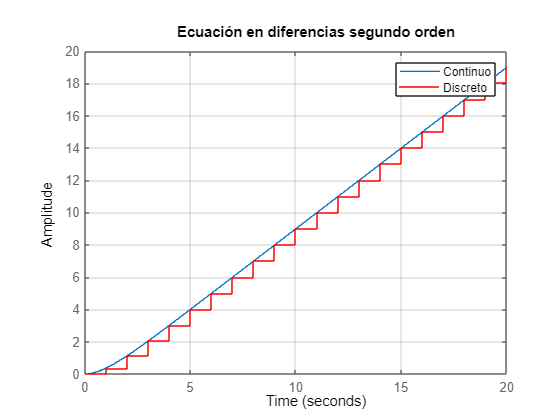

tsim = 20;
step(sys2,tsim)
hold on

ukm1 = 0;
ukm2 = 0;

xkm1 = 0;
xkm2 = 0;

k=0:T2:tsim;

for i=1:length(k)

    xk(i)=ukm1*0.3679+ukm2*0.2642+xkm1*1.368-xkm2*0.3679;% Ts=1 seg
    % xk(i)=ukm1*0.0288+ukm2*0.0265+xkm1*1.779-xkm2*0.7788; Ts=0.25 seg
    
    ukm2 = 0;
    xkm2 = 0;

    if i>=2
        ukm2 = ukm1;
        xkm2 = xkm1;
    end
    ukm1 = 1;
    xkm1 = xk(i);


end
stairs(k,xk,'r')
title('Ecuación en diferencias segundo orden')
legend('Continuo','Discreto')
grid on
hold off